# Audio information

clear all; close all; clc;
input_file = 'ELE725_lab1.wav';
[y,Fs] = audioread(input_file); info = audioinfo(input_file)

info = struct with fields:
             Filename: 'C:\Users\Christophe\Desktop\Lab1\code\ELE725_lab1.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 44100
         TotalSamples: 116736
             Duration: 2.6471
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


% file size according to audio info = 16 bits/sample * 44100 sample/sec * 2.6471 s = 1867776 bits = 233472 Bytes = 228 kB
% file size = 467 KB, shown in system property

## Sampling

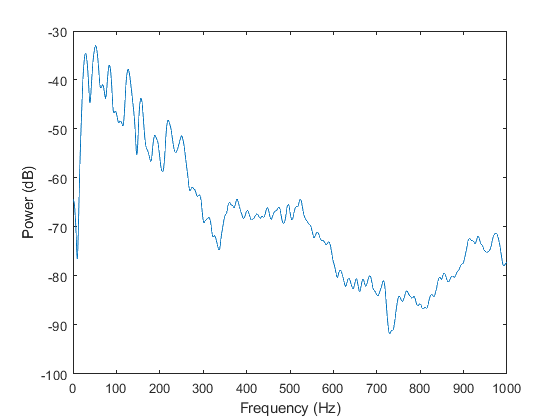

clear all; close all; clc;
input_file='ELE725_lab1.wav';downsample_file='ELE725_lab1_downsampled.wav';pf=false;p_time=2.7;

%original audio analysis
[y, Fs] = audioread(input_file);
%sound(y,Fs); pause(p_time);

%plotting spectra
figure();
p_spec = pspectrum(y);
plot(pow2db(p_spec(1:1000)));xlabel('Frequency (Hz)');ylabel('Power (dB)');
saveas(gcf,'./figures/original_spectra.png');

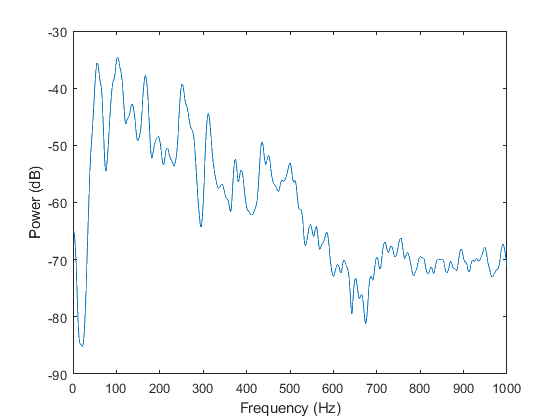

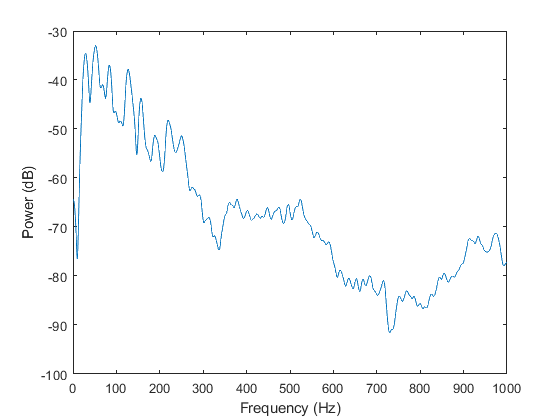

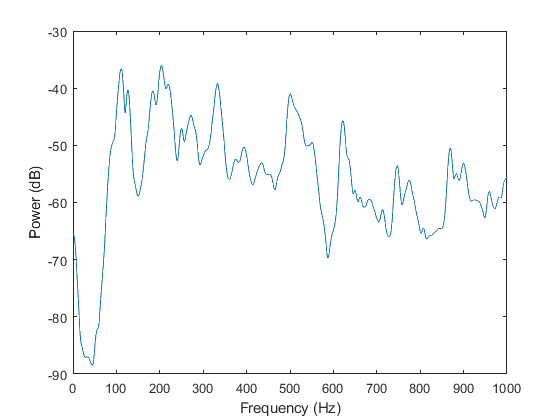

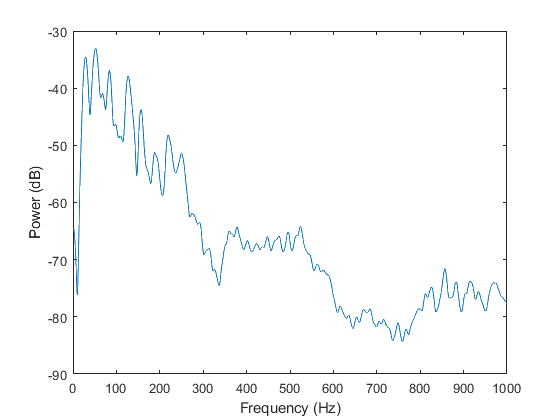

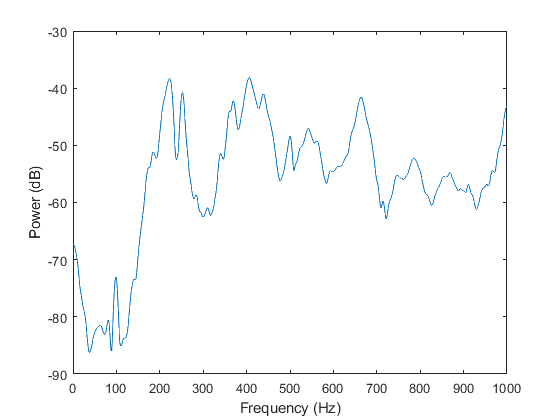

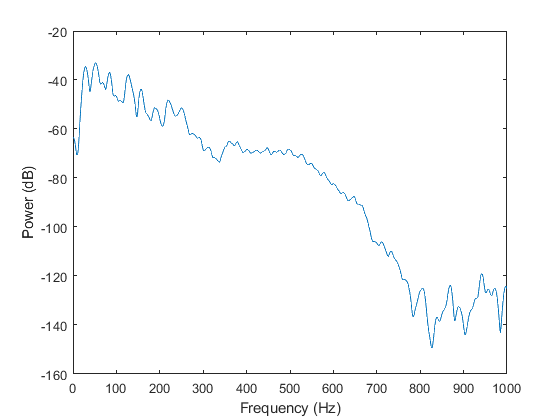


%analysis by iterating through downsampling rates
for N = [2,4,8]
    %filename=['./figures/downsampled_N',N,'.png'];
    DownSample(input_file, downsample_file, N, pf);  
    [down_sampled,Fs] = audioread(downsample_file);
    %plotting downsampled spectra
    figure();
    p_spec = pspectrum(down_sampled);
    plot(pow2db(p_spec(1:1000)));xlabel('Frequency (Hz)');ylabel('Power (dB)');
    saveas(gcf,sprintf('./figures/downsampled_spectra_N%d.png',N));
    
    %separating 2 channels of audio data to use interpolation function
    left_interp = interp(down_sampled(:,1),N); right_interp = interp(down_sampled(:,2),N);
    reconstructed = [left_interp,right_interp];
    %pause(p_time); sound(reconstructed,Fs); pause(p_time);

    %plotting reconstructed spectra
    figure();
    p_spec = pspectrum(reconstructed);  
    plot(pow2db(p_spec(1:1000)));xlabel('Frequency (Hz)');ylabel('Power (dB)');
    saveas(gcf,sprintf('./figures/reconstructed_spectra_N%d.png',N));
end

% as downsampling rate increases, the reconstructed sound loses fidelity
%In the time domain, when downsampling occurs, the signal gets compressed; while on upsampling, the signal gets stretched.
%Then, from the Fourier transform we know that time stretching means frequency compression, and vice-versa.

## Quantization

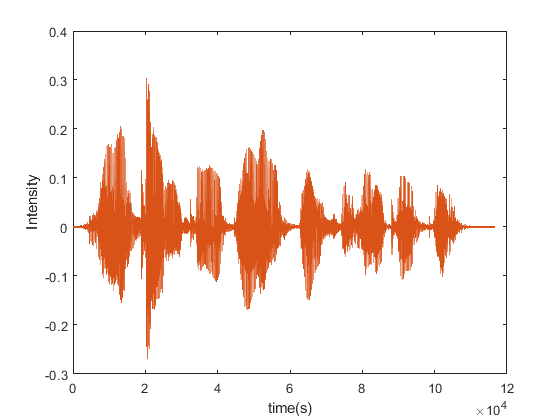

clear all; close all; clc;
input_file='ELE725_lab1.wav';u_q_file='ELE725_lab1_uniform_quantized.wav';
m_q_file = 'ELE725_lab1_mulaw_quantized.wav'; p_time=2.7;
%original audio
[original, Fs] = audioread(input_file);
figure(); 
plot(original); xlabel('time(s)'); ylabel('Intensity');
saveas(gcf,'./figures/original_wave.png');  

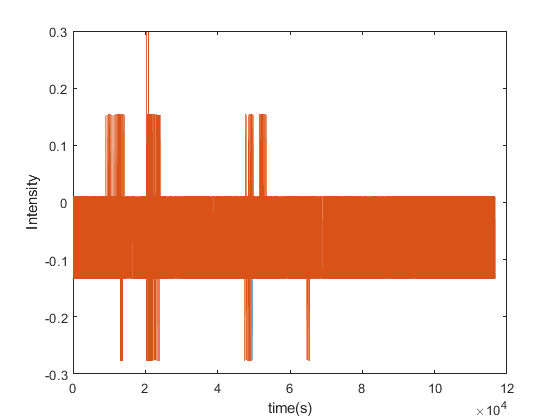

MSE of 2 bit uniform quantization is 0.0069652   0.0069633


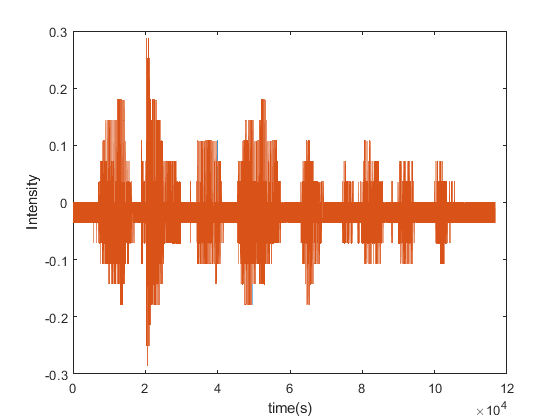

MSE of 4 bit uniform quantization is 0.000447   0.0004467


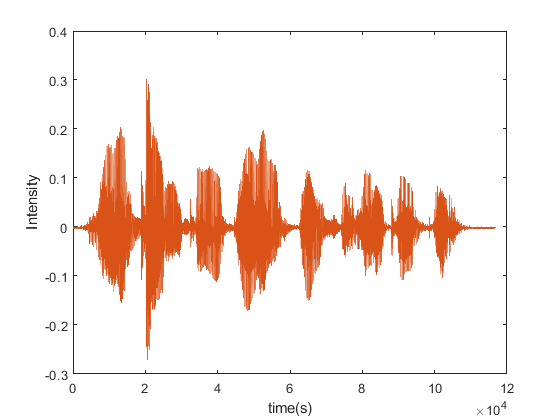

MSE of 8 bit uniform quantization is 1.7128e-06  1.7105e-06


%sound(original,Fs); pause(p_time);

%uniform quantizing to N bit
for N = [2,4,8]
    UniformQuant(input_file, u_q_file, N);
    [u_quantized,Fs] = audioread(u_q_file);
    %sound(u_quantized,Fs); pause(p_time);
    %waveform plot of audio data with N bit quantization
    figure();     
    plot(u_quantized); xlabel('time(s)'); ylabel('Intensity');
    saveas(gcf,sprintf('./figures/uniform_wave_N%d.png',N));
    disp(['MSE of ' num2str(N) ' bit uniform quantization is ' num2str(MSE_calc(original, u_quantized))]);
end

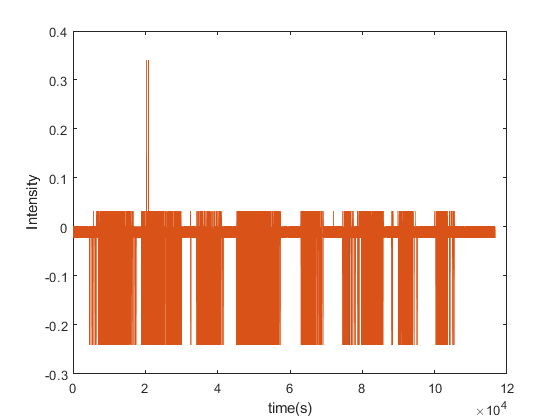

MSE of 2 bit mu-law quantization is 0.007004   0.0069999


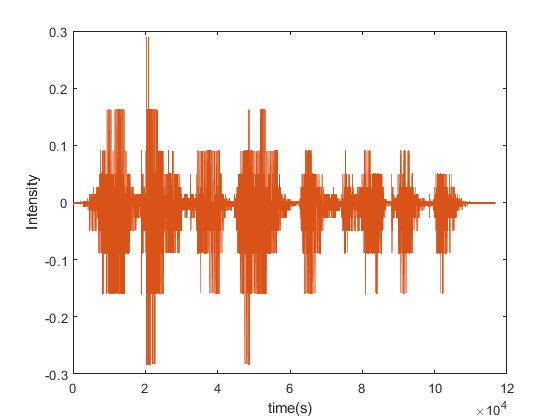

MSE of 4 bit mu-law quantization is 0.00022257  0.00022232


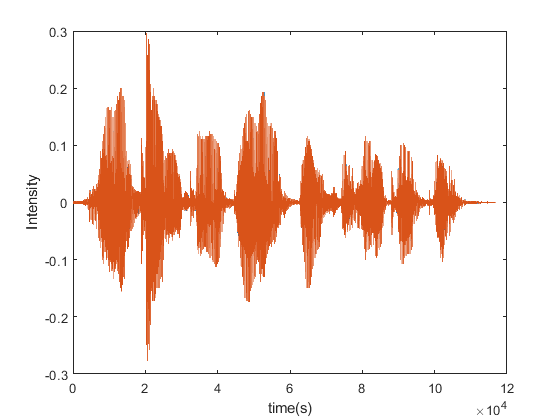

MSE of 8 bit mu-law quantization is 8.9875e-07  8.9807e-07


%sound quality reduces as bit number reduces, with more artifacts

%mu law quantization to N bit
Mu = 100;
for N = [2,4,8]
    MulawQuant(input_file, m_q_file, N, Mu);
    [m_quantized,Fs] = audioread(m_q_file);
    %sound(m_quantized,Fs); pause(p_time);
    %waveform plot of audio data with N bit quantization
    figure();     
    plot(m_quantized); xlabel('time(s)'); ylabel('Intensity');
    saveas(gcf,sprintf('./figures/mulaw_wave_N%d.png',N));
    disp(['MSE of ' num2str(N) ' bit mu-law quantization is ' num2str(MSE_calc(original, m_quantized))]);
end

%sound quality reduces as bit number reduces, with more artifacts

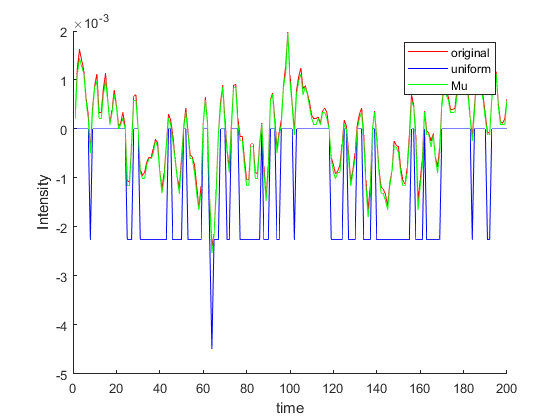

figure();
hold on
plot(original(1:200),'r');
plot(u_quantized(1:200),'b');
plot(m_quantized(1:200),'g');
legend('original','uniform','Mu');
xlabel('time'); ylabel('Intensity');
hold off
saveas(gcf,sprintf('./figures/200_waveform_comparison.png'));

disp(['MSE of 1-200 uniform quantization is ' num2str(MSE_calc(original(1:200), u_quantized(1:200)))]);

MSE of 1-200 uniform quantization is 1.5431e-06


disp(['MSE of 1-200 mu-law quantization is ' num2str(MSE_calc(original(1:200), m_quantized(1:200)))]);

MSE of 1-200 mu-law quantization is 8.1677e-09


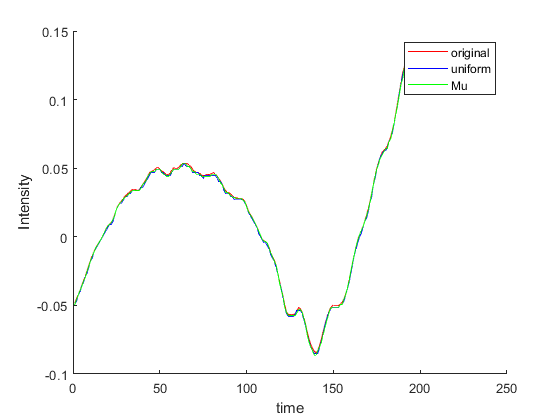


figure();
hold on
plot(original(49800:50000),'r');
plot(u_quantized(49800:50000),'b');
plot(m_quantized(49800:50000),'g');
legend('original','uniform','Mu');
xlabel('time'); ylabel('Intensity');
hold off
saveas(gcf,sprintf('./figures/50000_waveform_comparison.png'));

disp(['MSE of 1-200 uniform quantization is ' num2str(MSE_calc(original(4800:5000), u_quantized(4800:5000)))]);

MSE of 1-200 uniform quantization is 1.8053e-06


disp(['MSE of 1-200 mu-law quantization is ' num2str(MSE_calc(original(4800:5000), m_quantized(4800:5000)))]);

MSE of 1-200 mu-law quantization is 1.2504e-07
